### Exercise 1

#### c.

% Code from provided script RTLSDRMatlabStream.m
% Make sure RTLSDR receiver is connected properly before running

fs = 300e3; % this is the sample rate
fc = 90.8e6; % this is the center frequency (NPR)

x = zeros(3e6,1); % empty vector to store data

% create object for RTL-SDR receiver
rx = comm.SDRRTLReceiver('CenterFrequency',fc, 'EnableTunerAGC', false, 'TunerGain', 35,  'SampleRate', fs);

counter = 1; % initialize a counter
while(counter < length(x)) % while the buffer for data is not full
    rxdata = rx();   % read from the RTL-SDR
    x(counter:counter + length(rxdata)-1) = rxdata; % save the samples returned
    counter = counter + length(rxdata); % increment counter
end
% the data are returned as complex numbers
% separate real and imaginary part, and remove any DC offset
y_I = real(x)-mean(real(x));
y_Q = imag(x)-mean(imag(x));

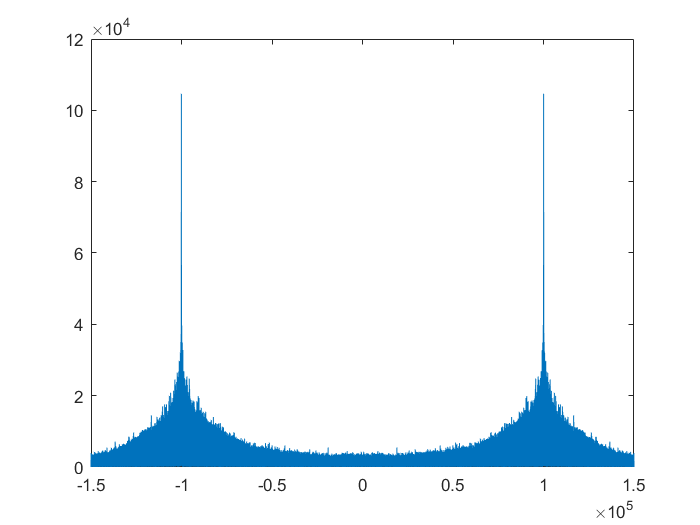

% Plot y_I in the frequency domain
plot_FT(y_I, fs);

#### d.

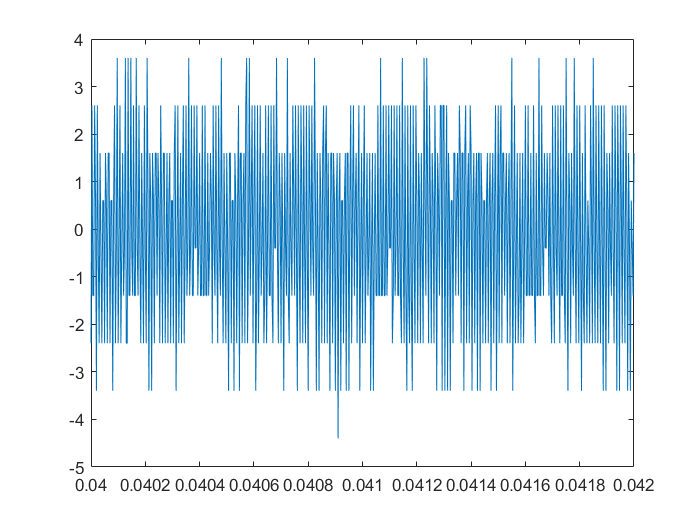

% Plot y_I in the time domain
t = linspace(0, length(y_I)/fs, length(y_I))';
plot(t, y_I)
xlim([0.040 0.042])

#### e.

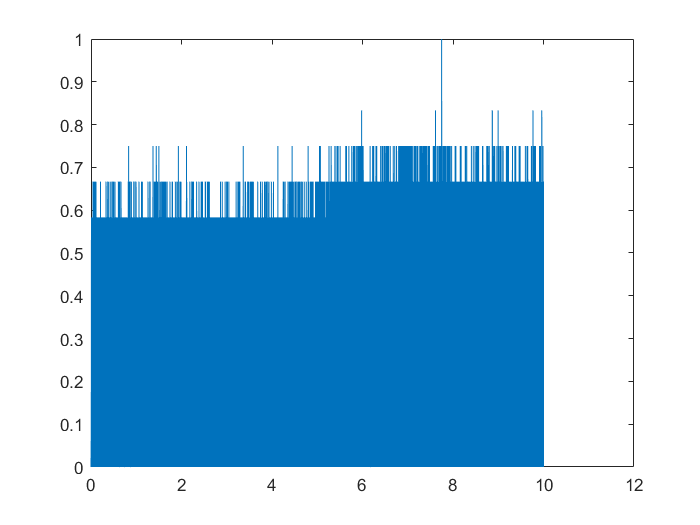

% Take the derivative of the signal
y_I_d = diff(y_I)./diff(t);
% Set negative values to zero
y_I_d(y_I_d < 0) = 0; 
% Rescale values between zero and one
y_I_d = rescale(y_I_d);
% Plot resulting signal
plot(t(1:end-1), y_I_d);

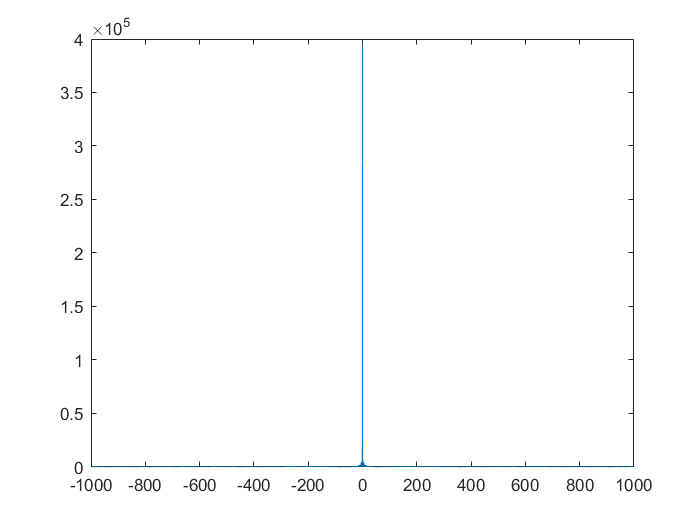

plot_FT(y_I_d, fs);
xlim([-1000 1000])

#### f.

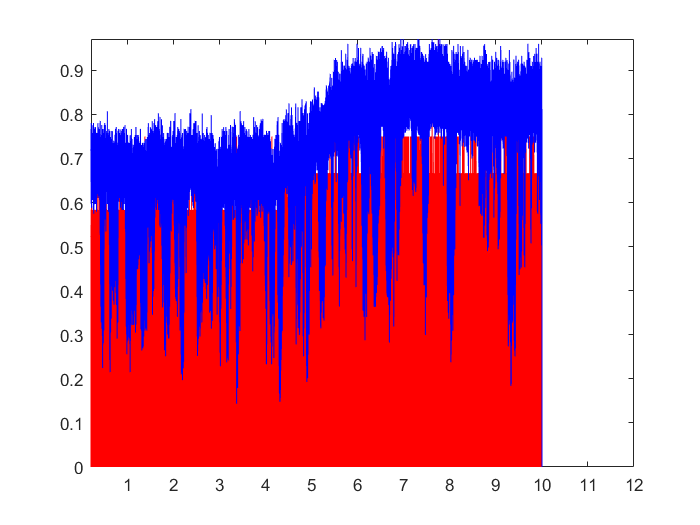

% Create low pass filter with sinc()
t_h = [-50:1:49]*(1/fs); % Creates 100 samples
h = 2*400*sinc(2*400*t_h);

% Convolve derivative of signal with low-pass filter and rescale
% values to be between zero and one
y_filt = rescale(conv(y_I_d, h));
% Plot resulting signal; the new signal captures
% the envelope of the received signal.
t_filt = linspace(0, length(y_filt)/fs, length(y_filt));
figure()
plot(t(1:end-1), y_I_d, "Red", t_filt, y_filt, "Blue");

f.

% Subtract the mean
y_mean_sub = y_filt - mean(y_filt);
% Rescale the data to have a max value of 0.1
y_rescaled = rescale(y_mean_sub, -0.1, 0.1);
% Decimate the signal and play the sound
y_rescaled = decimate(y_rescaled, 4);
soundsc(y_rescaled, fs/4)

2.

b.

% Code from provided script RTLSDRMatlabStream.m
% Make sure RTLSDR receiver is connected properly before running
% Copied here for linear flow of script and to 
% assign a new target radio station

fs = 300e3; % this is the sample rate
fc = 107.9e6; % this is the center frequency (Kiss 108)

x = zeros(3e6,1); % empty vector to store data

% create object for RTL-SDR receiver
rx = comm.SDRRTLReceiver('CenterFrequency',fc, 'EnableTunerAGC', false, 'TunerGain', 35,  'SampleRate', fs);

counter = 1; % initialize a counter
while(counter < length(x)) % while the buffer for data is not full
    rxdata = rx();   % read from the RTL-SDR
    x(counter:counter + length(rxdata)-1) = rxdata; % save the samples returned
    counter = counter + length(rxdata); % increment counter
end

Error using comm.SDRRTLReceiver/checkForError
Failed to communicate with radio 0. Check if your radio is connected to your computer or USB driver is installed.

Error in comm.SDRRTLReceiver/setupImpl

% the data are returned as complex numbers
% separate real and imaginary part, and remove any DC offset
y_I = real(x)-mean(real(x));
y_Q = imag(x)-mean(imag(x));

% Decode message with provided equation in Exercise 2
t_Q = linspace(0, length(y_Q)/fs, length(y_Q))';
t_I = linspace(0, length(y_I)/fs, length(y_I))';
m_decoded = (diff(y_Q)./diff(t_Q)).*y_I(1:end-1) - (diff(y_I)./diff(t_I)).*y_Q(1:end-1);
% Subtract the mean from the signal
m_centered = m_decoded - mean(m_decoded);
% Normalize and plot resulting signal
m_normalized = m_centered * 0.1 ./ max(abs(m_centered))

m_normalized =    -0.0230
   -0.0244
   -0.0244
   -0.0244
   -0.0257
   -0.0251
   -0.0257
   -0.0230
   -0.0257
   -0.0230


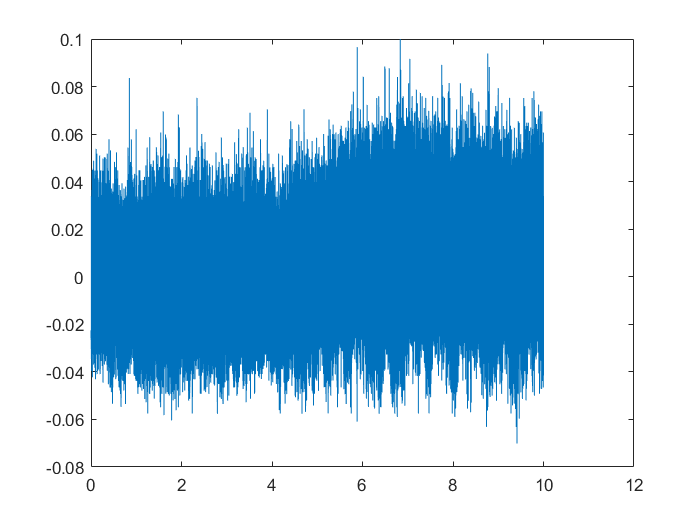

plot(t_I(1:end-1), m_normalized)

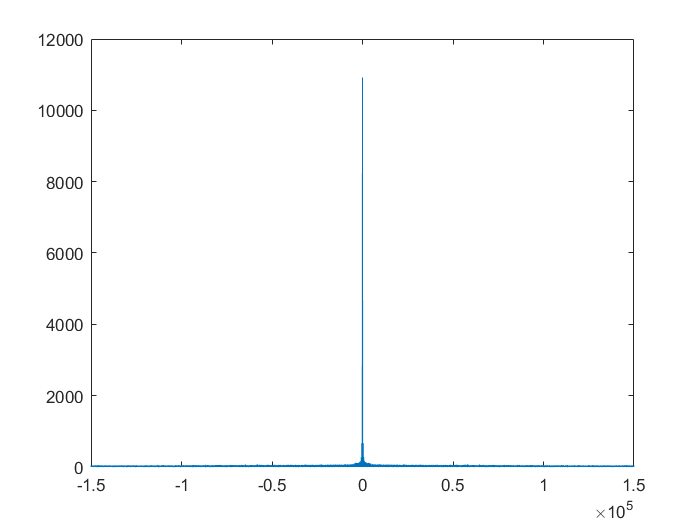

plot_FT(m_normalized, fs);

% Decimate and play sound
m_decimated = decimate(m_normalized, 4);
soundsc(m_decimated, fs/4);